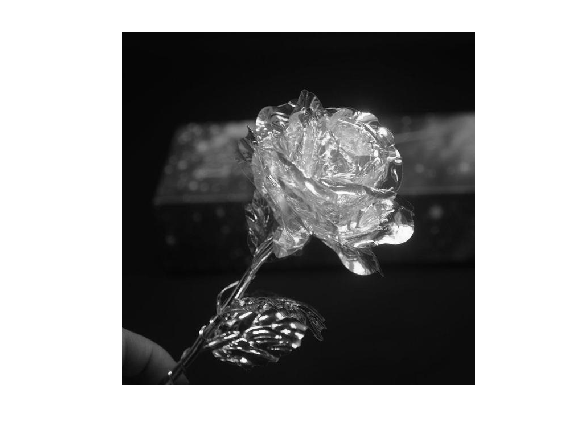

originalImage = imread('ROSE.jpg');
bin = rgb2gray(originalImage);

imshow(bin)

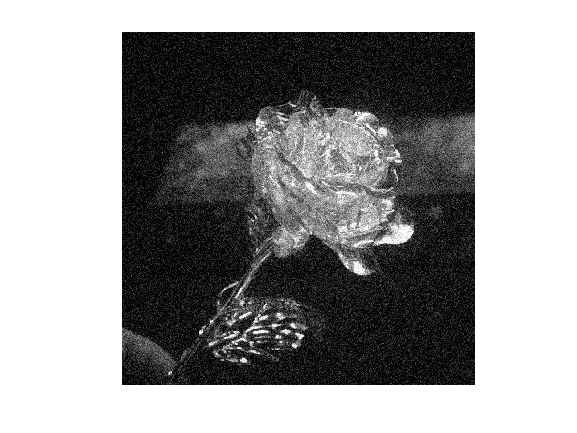

noisyImage = imnoise(originalImage,'gaussian');
imshow(noisyImage)

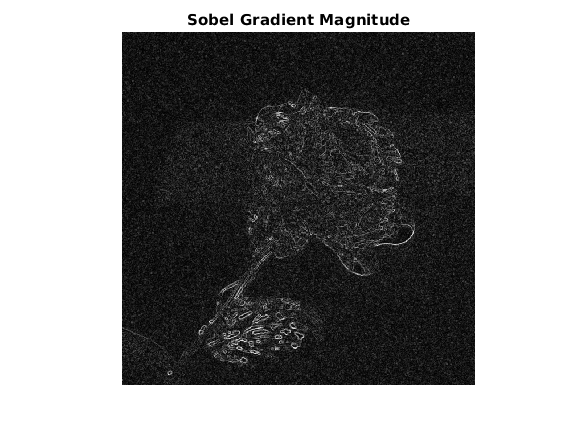

sobelGradient = imgradient(noisyImage);
imshow(sobelGradient,[])
title('Sobel Gradient Magnitude')

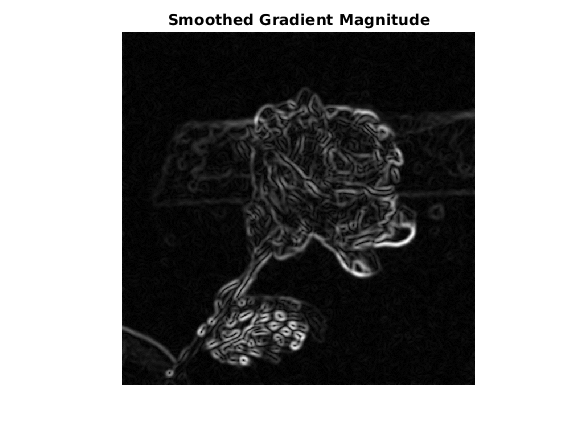

a =      2     4     8     8     7     2    23    78    14


ans = 8

%Even with the use of Sobel, Roberts or Prewitts gradient operators, 
% the image gradient may be too noisy. 
% To overcome this, smooth the image using a Gaussian smoothing filter 
% before computing image gradients. Use the imgaussfilt function to smooth the image.
sigma = 3;
smoothImage = imgaussfilt(noisyImage,sigma);
smoothGradient = imgradient(smoothImage,'CentralDifference');
imshow(smoothGradient,[])
title('Smoothed Gradient Magnitude')